# Maximum Likelihood

## Notes

This lesson demonstrates the use of a non-linear optimizer to (minimize a negative) log-likelihood. The LL is constrained and so it is usually reparameterized, although there is one example using `fmincon` to and constraints to ensure that the parameters stay in the allowable domain.

## Setup

Clear and reset the workspace and load required data

% Clean up everything
clear all
close all
clc
% Reset rng to make runs the same
rng('default')

## Maximum Likelihood

Maximum likelihood is a popular method to estimate parameters in econometric models. In many cases, closed form estimators are not available and so non-linear optimizers are required.

## Standardized Students-t Estimator

Estimating parameters requires using an optimizer (fminuc or fmincon) along with the **negative** log-likelihood. The optimizers all minimize functions which is why the negative log-likelihood is used. Testing log-likelihood is often difficult, and one of the more useful tests is to simulate a very large quantity of data and check that the optimum is close to the true value.

% Simulate data
nu = 8;
x = trnd(nu,1000,1);
x = x/sqrt(nu/(nu-2));
% Transformed value starting from true value of 8
nu0 = 2+log(6);
% Test the likelihood
std_studentst_loglike(nu0,x)

ans = 1.3933e+03

## Huge sample, evaluate on a grid

As a simple test, we can evaluate the LL on a grid near the truth to ensure that the maximum is close to the truth

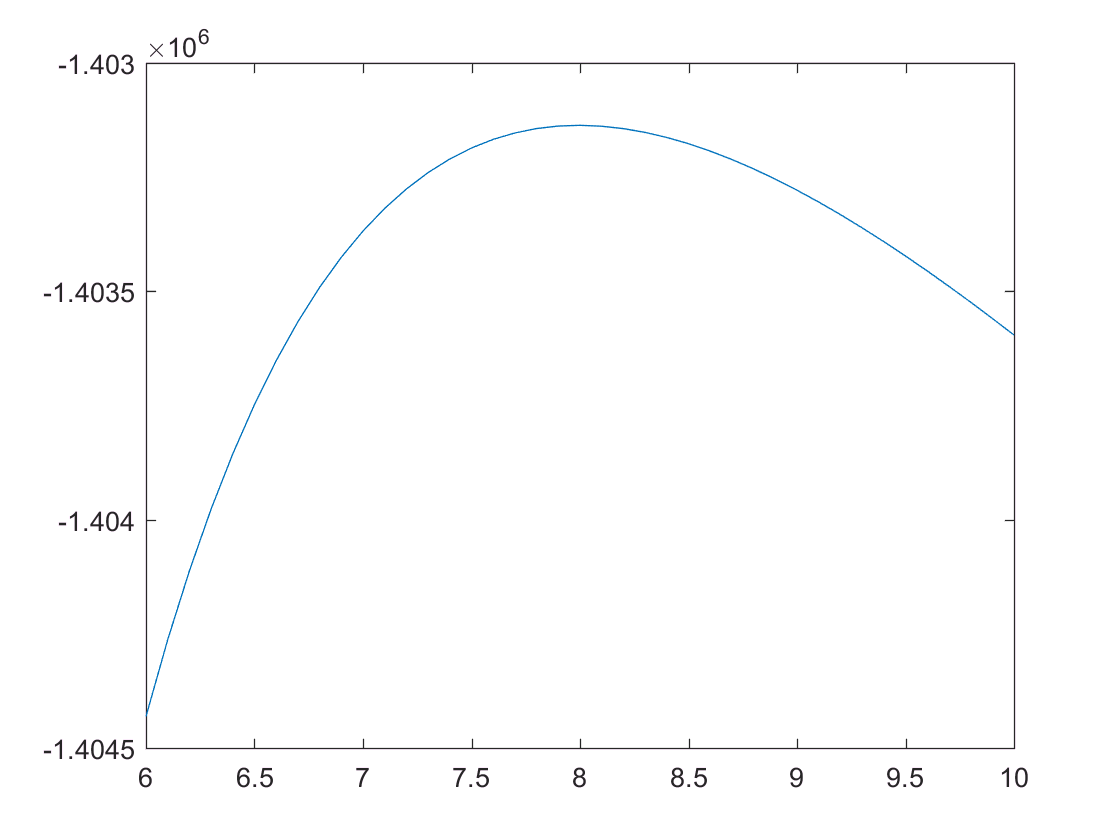

% Huge sample
x = trnd(nu,1000000,1);
x = x/sqrt(nu/(nu-2));
% Transformed value starting from true value of 8
nus = 6:.1:10;
neg_log_likes = zeros(size(nus));
for i=1:length(nus)
    nu0 = log(nus(i) - 2);
    % Test the likelihood
    neg_log_likes(i) = std_studentst_loglike(nu0,x);
end
pos_log_likes = -neg_log_likes;
plot(nus,pos_log_likes)

[~,loc] = max(pos_log_likes);
disp('Highest LL at')

Highest LL at


disp(nus(loc))

     8



## Load the data

load SP_FTSE

## Optimization

This example uses unconstrained optimization through fminunc which is a problem since nu must be larger than 2. Reparameterization is used where nu is replaced by 2+exp(nu-tilde) which will always be larger than 2. The options are used to avoid some annoying warning messages and to suppress all display which makes the output easier to read.

options = optimset('fminunc');
options.Display = 'off';
options.Algorithm = 'quasi-newton';
options.LargeScale = 'off';
% Estimate the parameters
x = 100*diff(log(SP500_monthly(:,3)));
mu = mean(x);
sigma2 = var(x);
% Standardize
z = (x-mu)/sqrt(sigma2);
% Estimate
nu_est = fminunc(@std_studentst_loglike,nu0,options,z);
% Transform back
nu_est_final = 2 + exp(nu_est);

## Estimate all parameters jointly

The previous estimation only estimated nu. This second example estimates all parameters using ML: the mean, variance and the degree of freedom. This requires reparameterizing the variance using a square.

% Starting values
sv = [mean(x) std(x) nu0];
% Estimation
parameters_est = fminunc(@std_studentst_loglike_mean_var,sv,options,x);
% Transform back
parameters_final = [parameters_est(1) parameters_est(2)^2 2+exp(parameters_est(3))];
saved_parameters = parameters_final;
% Display
disp('S&P 500 Monthly')

S&P 500 Monthly


disp('nu only')

nu only


disp([mu sigma2 nu_est_final])

    0.6010   17.6902    6.7912



disp('mu, sigma2 and nu')

mu, sigma2 and nu


disp(parameters_final)

    0.7840   17.5967    6.5560



## Use cell array to loop over all series

Cell arrays are similar to matrices but can contain virtually anything in MATLAB. In this example, I use a for loop plus the code above along with 2 cell arrays to loop over all series. The first cell array contains the data and the second contains the labels.

Looping over horizons shows that higher frequency returns have havier tails.

all_data = {SP500_monthly,SP500_weekly,SP500_daily,...
    FTSE100_monthly,FTSE100_weekly,FTSE100_daily};
labels = {'S&P 500 Monthly','S&P 500 Weekly','S&P 500 Daily',...
    'FTSE 100 Monthly','FTSE 100 Weekly','FTSE 100 Daily'};

% Loop over series
for i=1:6
    data = all_data{i};
    % Estimate the parameters
    x = 100*diff(log(data(:,3)));
    mu = mean(x);
    sigma2 = var(x);
    % Standardize
    z = (x-mu)/sqrt(sigma2);
    % Estimate
    nu_est = fminunc(@std_studentst_loglike,nu0,options,z);
    % Transform back
    nu_est_final = 2 + exp(nu_est);
    
    % Starting values
    sv = [mean(x) std(x) nu0];
    % Estimation
    parameters_est = fminunc(@std_studentst_loglike_mean_var,sv,options,x);
    % Transform back
    parameters_final = [parameters_est(1) parameters_est(2)^2 2+exp(parameters_est(3))];
    % Display
    disp(labels{i})
    disp('nu only')
    disp([mu sigma2 nu_est_final])
    disp('mu, sigma2 and nu')
    disp(parameters_final)
end

S&P 500 Monthly


nu only


    0.6010   17.6902    6.7912



mu, sigma2 and nu


    0.7840   17.5967    6.5560



S&P 500 Weekly


nu only


    0.1399    4.6138    4.9517



mu, sigma2 and nu


    0.2136    4.4327    5.1428



S&P 500 Daily


nu only


    0.0290    0.9539    3.3219



mu, sigma2 and nu


    0.0466    1.0305    3.1401



FTSE 100 Monthly


nu only


    0.4919   21.5084    5.8392



mu, sigma2 and nu


    0.8070   21.0740    5.5452



FTSE 100 Weekly


nu only


    0.1174    5.7616    4.2157



mu, sigma2 and nu


    0.2164    5.5686    4.3227



FTSE 100 Daily


nu only


    0.0241    1.2477    3.9080



mu, sigma2 and nu


    0.0502    1.2540    3.8724



## Using constrained optimization

`fminunc` can be used to estimate the model without reparameterization. This example assumes that $\nu> 2.05$ and $\sigma^2>$ variance of the data divided by 100.

The constraints are all lower bound, which can be implemented using a vector (see `doc fmincon`)

% Estimate the parameters
x = 100*diff(log(SP500_monthly(:,3)));
% Starting values
sv = [mean(x) std(x) nu0];
% Lower bounds
lb = [-inf,var(x)/100,2.05];
fun = @std_studentst_loglike_mean_var_notrans;
options = optimset('fmincon');
% Show additional information
options.Diagnostics = 'on';
% Show iterative output
options.Display = 'iter';
% Change the algorithm to avoid warning/error
options.Algorithm='sqp';
% Estimate parameter
constrained_parameters = fmincon(fun,sv,[],[],[],[],lb,[],[],options,x);


____________________________________________________________
   Diagnostic Information

Number of variables: 3

Functions 
Objective:                            std_studentst_loglike_mean_var_notrans
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      0
Number of lower bound constraints:          2
Number of upper bound constraints:          0

Algorithm selected
   sqp


____________________________________________________________
   End diagnostic information
                                                          Norm of First-order
 Iter F-count            f(x) Feasibility  Steplength        step  optimality
    0       4    3.480770e+03   0.000e+00                           6.567e+03
    1      16    2.981773e+03   0.000e+00   5.765e-02   3.787

% Show parameters
disp('Estimates')

Estimates


disp(constrained_parameters)

    0.7840   17.5967    6.5559



disp('Using reparameterization')

Using reparameterization


disp(saved_parameters)

    0.7840   17.5967    6.5560



## Simulating Bernoullis

This simulates Bernoullis using the normal CDF to constrain the true probability to be between 0 and 1

% Number of simulations
B = 1000;
% Exogenous variables
x = randn(B,1);
% Transform to probabilities
p = normcdf(x);
% 1 is a uniform is larger than p
y = p>rand(B,1);

% Test the loglikelihood
probit_loglike([0 1],y,x)

ans = 531.5717

% Restore fminunc options
options = optimset('fminunc');
options.Display = 'off';
options.Algorithm = 'quasi-newton';
options.LargeScale = 'off';
% Change the display to iter to show the progress
options.Display='iter';
% Optimize the log-likelihoods
probit_parameters = fminunc(@probit_loglike,[0 1],options,y,x);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           3          531.572                          31.8
     1           9          529.773     0.00325688           6.85  
     2          12          529.732              1           2.92  
     3          15          529.722              1         0.0181  
     4          18          529.722              1       0.000732  
     5          21          529.722              1       2.29e-05  

Local minimum found.

Optimization completed because the size of the gradient is less than
the selected value of the 

disp(probit_parameters)

    0.0177    0.8910



## Covariance

Use analytical formulas to estimate the covariance of the scores. This requires some pencil and paper work to compute the derivatives as


$$y_i \phi(\hat{y}_i) / \Phi(\hat{y}_i) - (1-y_i)  \phi(\hat{y}_i) / (1-\Phi(\hat{y}_i))$$


and


$$y_i x_i \phi(\hat{y}_i) / \Phi(\hat{y}_i) - (1-y_i)x_i  \phi(\hat{y}_i) / (1-\Phi(\hat{y}_i))$$


where 


$$\hat{y}_i = a_0+a_1 x_i$$


% Compute scores
a0 = probit_parameters(1);
a1 = probit_parameters(2);
pdf = normpdf(a0+a1*x);
cdf = normcdf(a0+a1*x);
scores_a0 = y .* pdf ./ cdf - (1-y) .* pdf ./ (1-cdf);
scores_a1 = y .* x .* pdf ./ cdf - (1-y) .* x  .* pdf ./ (1-cdf);

scores = [scores_a0 scores_a1];
% Check score mean
disp('Check the mean of the scores')

Check the mean of the scores


disp(mean(scores))

   1.0e-07 *

    0.1511    0.3988



n = B;
% Asymptotic inverse covariance using scores of log-like
asym_param_cov = inv(scores'*scores / n);
% Std err is sqrt of asymptotic cov divided by n
standaard_err = sqrt(diag(asym_param_cov)/n);
% Display results
disp('Bernoulli')

Bernoulli


disp('Standard error')

Standard error


disp(standaard_err)

    0.0445
    0.0604



disp('T-stat')

T-stat


disp(probit_parameters./standaard_err')

    0.3973   14.7478

